# Principles and Consequences of the Initial Visual Encoding

The code illustrates how we used ISETBio to create several of the image components in the chapter.

## Run this code from inside the repository directory

This is used to access the oiData.mat file that is stored in the directory.

chdir(fileparts(which('s_ashbyChapter.m')));

## Spectral band RGB images

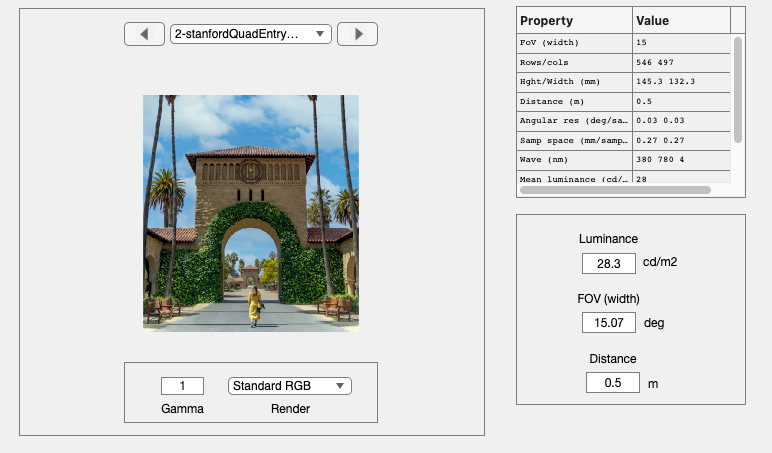

scene = sceneFromFile('stanfordQuadEntryLowRes.png','rgb',[],displayCreate);
sceneWindow(scene);

### Make little narrow band images

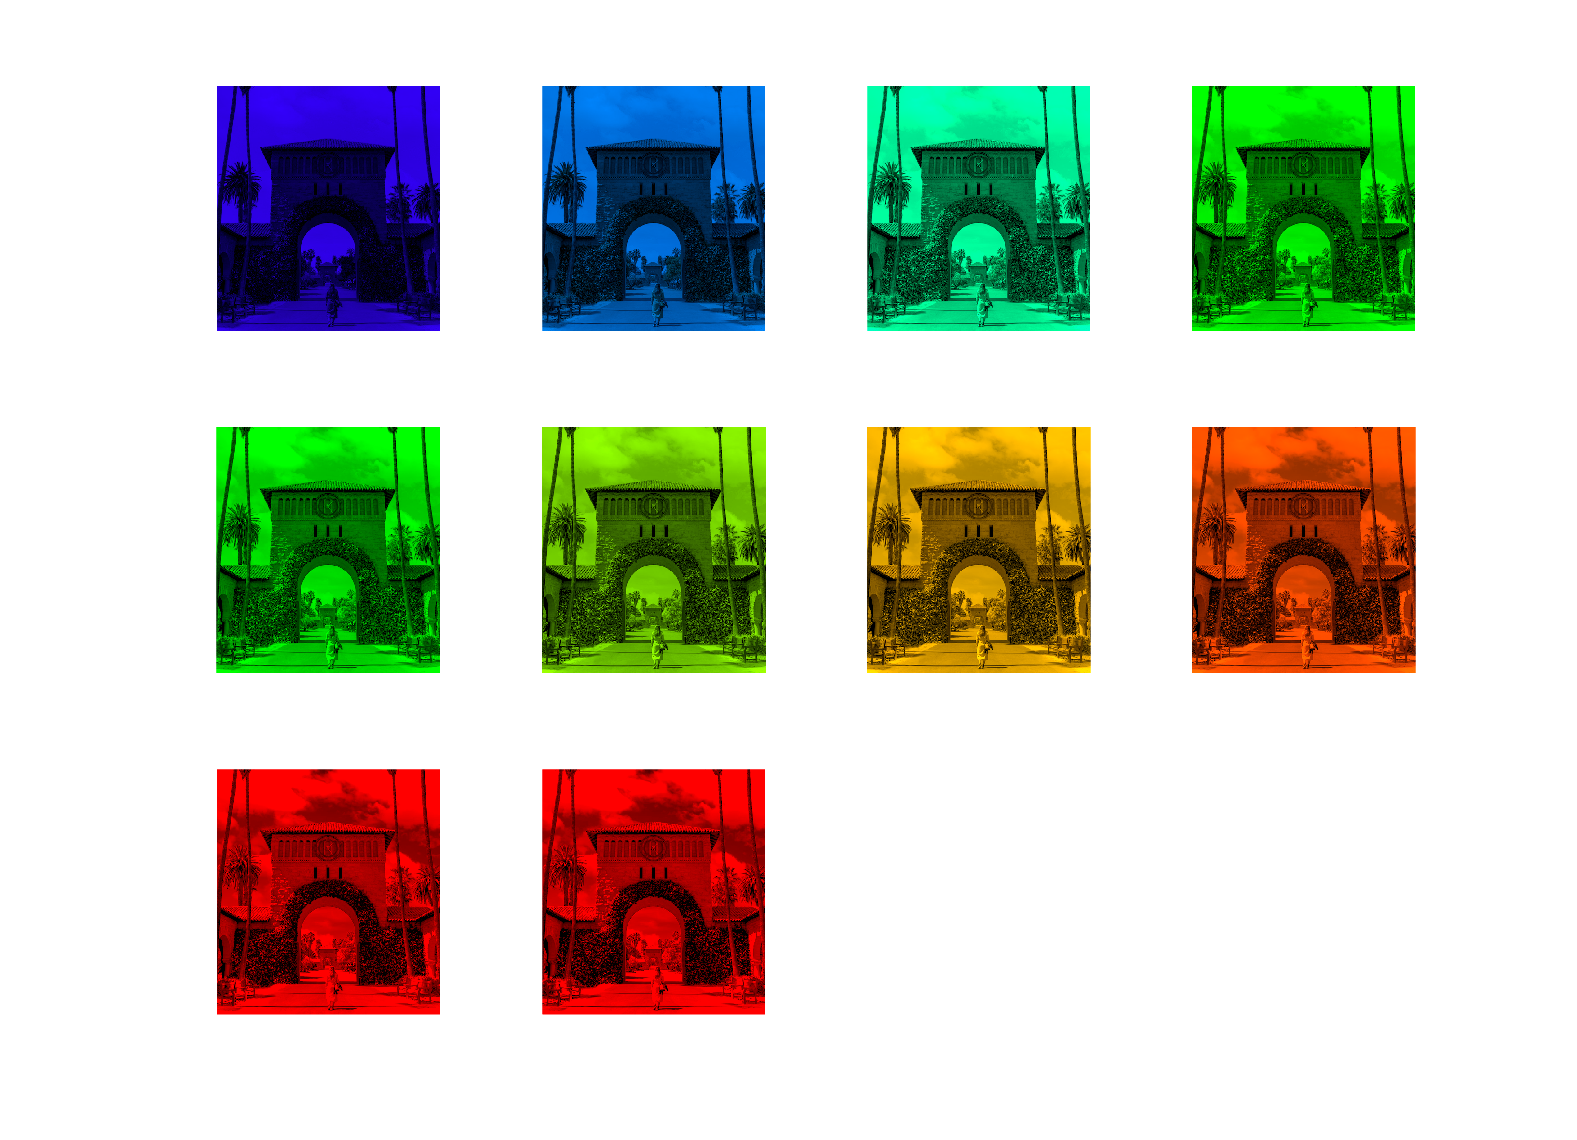

nBands = 10;
rgb = cell(nBands,1);
for ii=1:nBands
    newWave = (450:10:470) + (ii-1)*20;
    tmp = sceneSet(scene,'wave',newWave);
    rgb{ii} = sceneGet(tmp,'rgb');
end

ieNewGraphWin;
for ii=1:nBands
    subplot(3,4,ii)
    imshow(rgb{ii});
end

## Noise distribution graphs

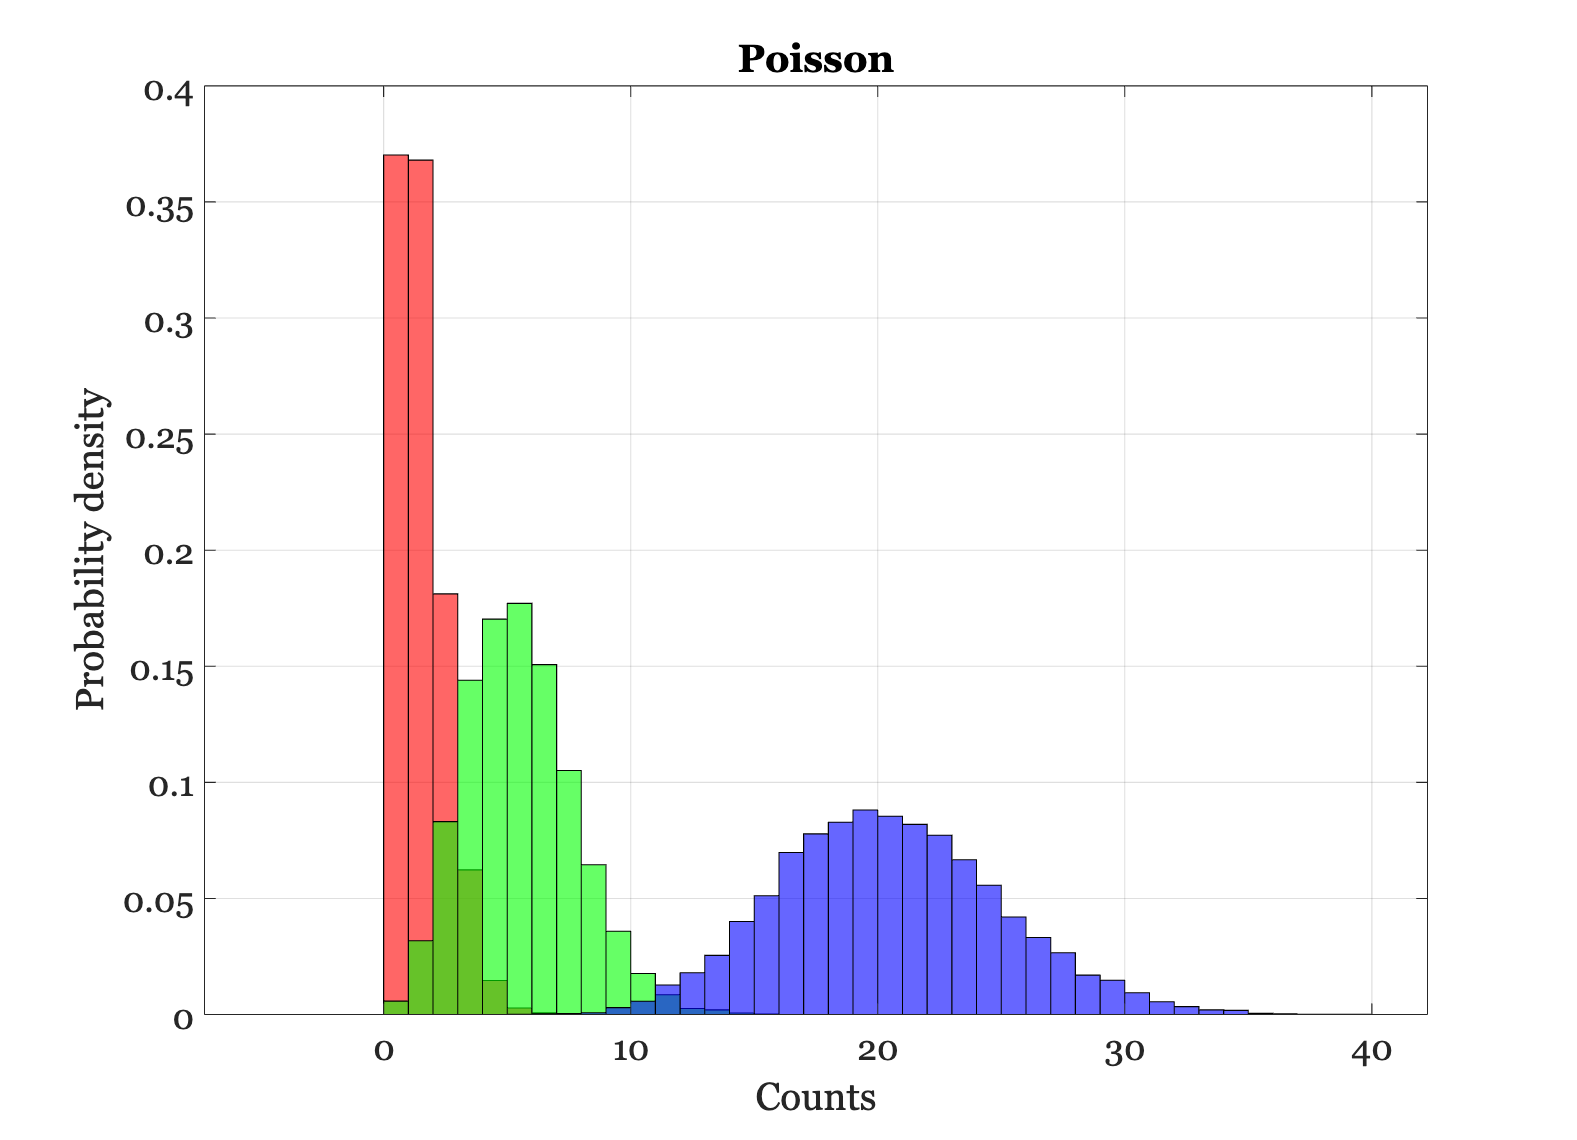

lambda = [1 5 20];
nSamp = 10000;

% Poisson
ieNewGraphWin;

val = zeros(nSamp,numel(lambda));
for ii=1:numel(lambda)
    val(:,ii) = iePoisson(lambda(ii),'nSamp',[nSamp,1]);
end

h = histogram(val(:,1),'Normalization','pdf'); hold on;
h.BinLimits = [-5 40]; h.BinWidth = 1; % h.FaceColor = [0.8 0.8 0.8];

h = histogram(val(:,2),'Normalization','pdf');
h.BinLimits = [-5 40]; h.BinWidth = 1; % h.FaceColor = [0.5 0.5 0.5];

h = histogram(val(:,3),'Normalization','pdf');
h.BinLimits = [-5 40]; h.BinWidth = 1; % h.FaceColor =  [0.2 0.2 0.2];

grid on
title('Poisson');
xlabel('Counts');
ylabel('Probability density')

### Poisson noise histograms

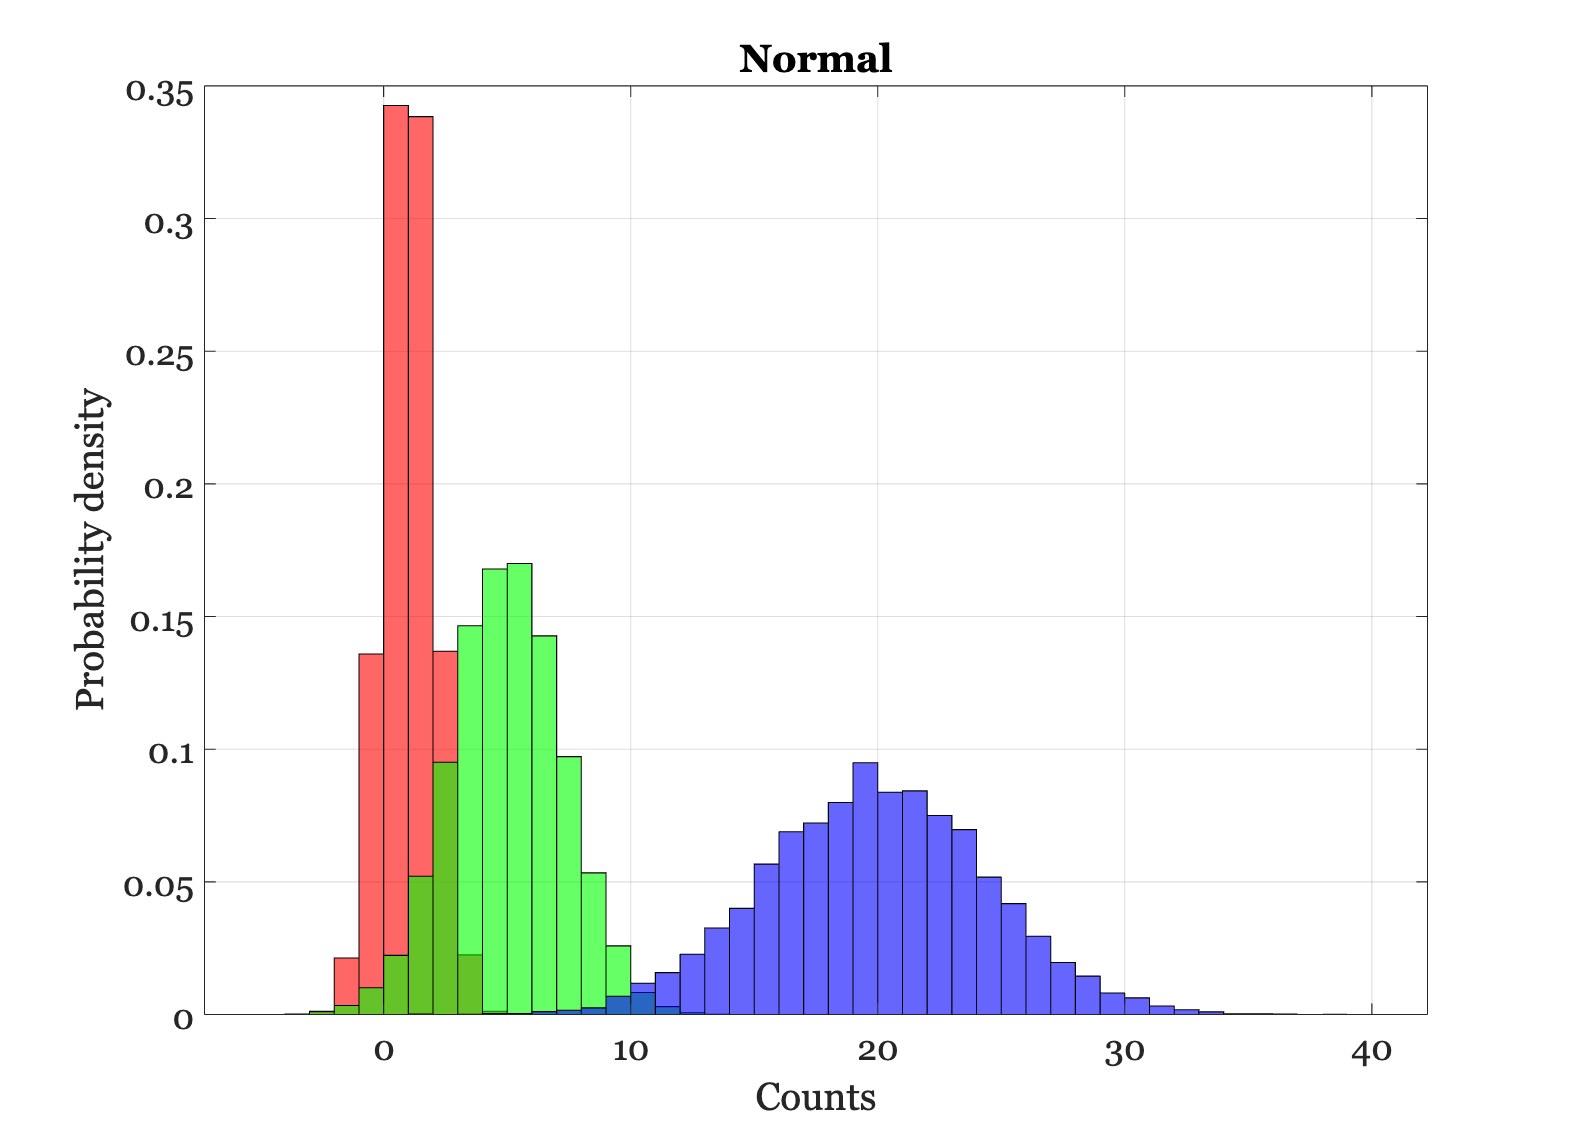

ieNewGraphWin;

val = zeros(nSamp,numel(lambda));
for ii=1:numel(lambda)
    val(:,ii) = sqrt(lambda(ii))*randn(nSamp,1) + lambda(ii);
end

h = histogram(val(:,1),'Normalization','pdf'); hold on;
h.BinLimits = [-5 40]; h.BinWidth = 1; % h.FaceColor = [0.8 0.8 0.8];
h = histogram(val(:,2),'Normalization','pdf');
h.BinLimits = [-5 40]; h.BinWidth = 1; % h.FaceColor = [0.5 0.5 0.5];
h = histogram(val(:,3),'Normalization','pdf');
h.BinLimits = [-5 40]; h.BinWidth = 1; % h.FaceColor = [0.2 0.2 0.2];
grid on
title('Normal');
xlabel('Counts');
ylabel('Probability density')

## Cone fundamentals

Load a stored cone mosaic.  You can use cMosaic to create a mosaic from scratch.

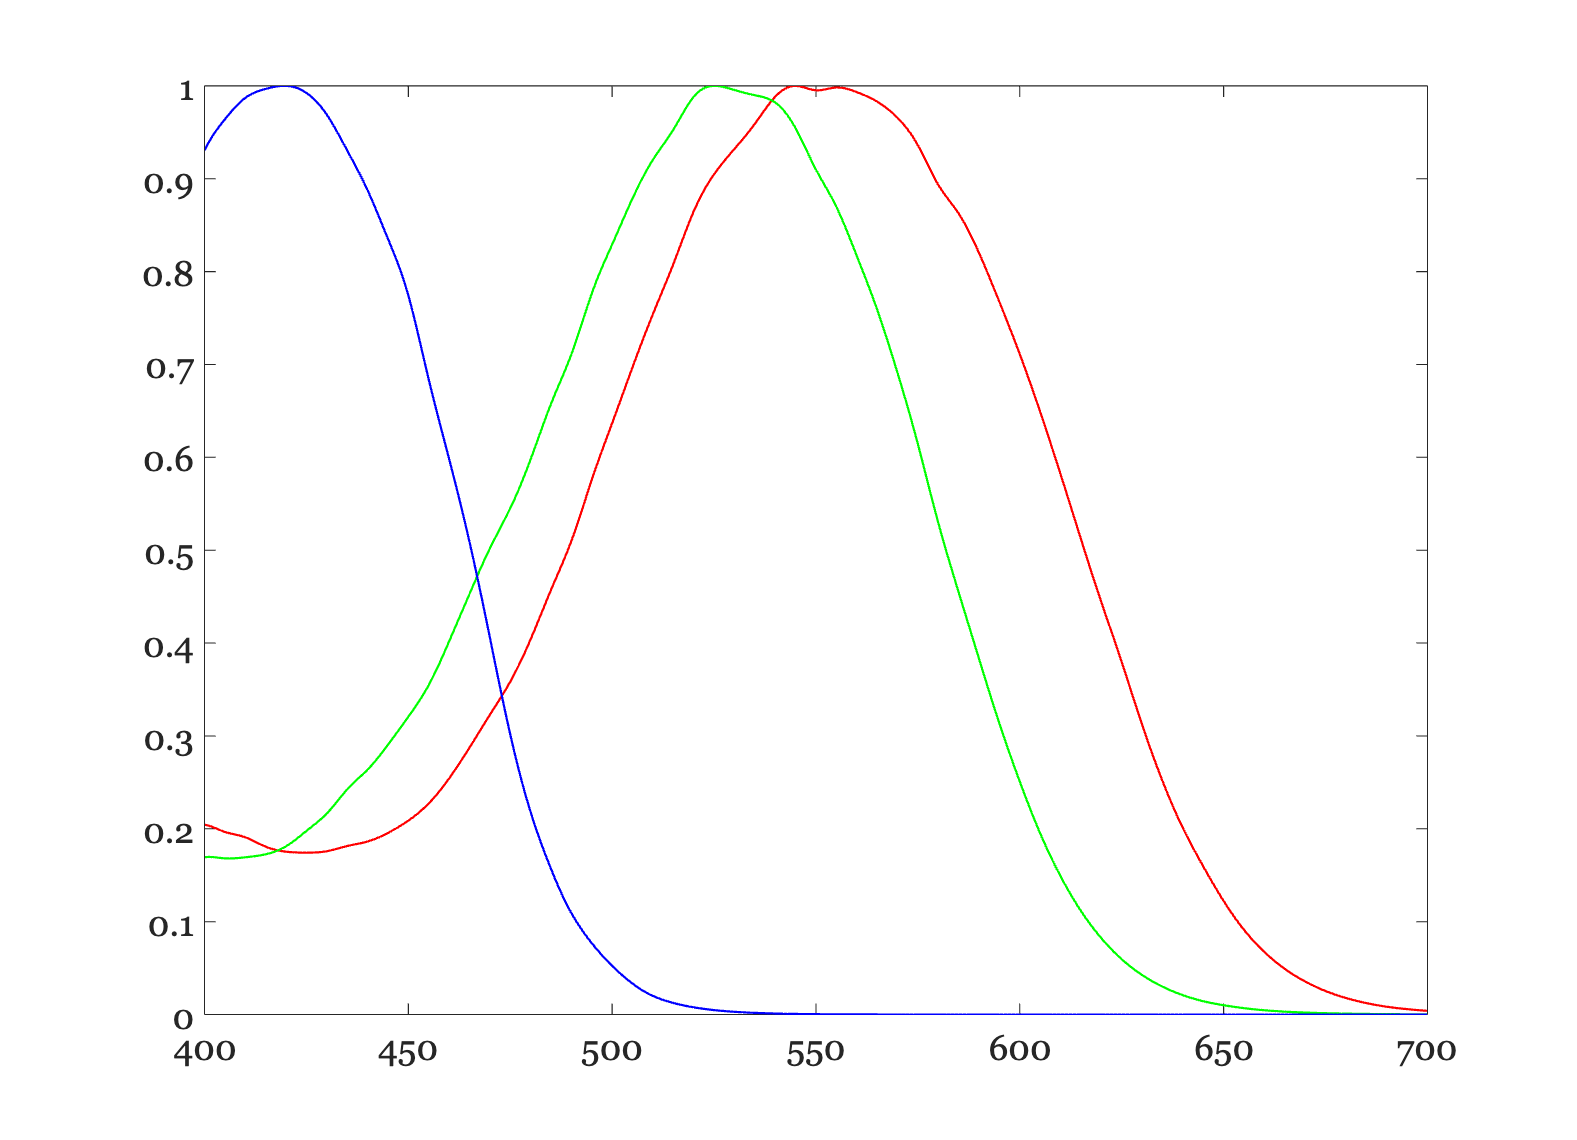

theMosaic = mosaicLoad('cmosaic_0.5-0.5_0.0-0.0');theMosaic.wave = 400:1:700;
theLens = Lens;
theLens.wave = 400:1:700;
wave = theMosaic.wave;

theMosaic.macular.density = 0.35; % 0.35 is Default
theMosaic.macular.eccDensity(0:1:15);
theLens.density = 1; % 1 is default
ieNewGraphWin; plot(wave,theMosaic.pigment.quantaFundamentals);

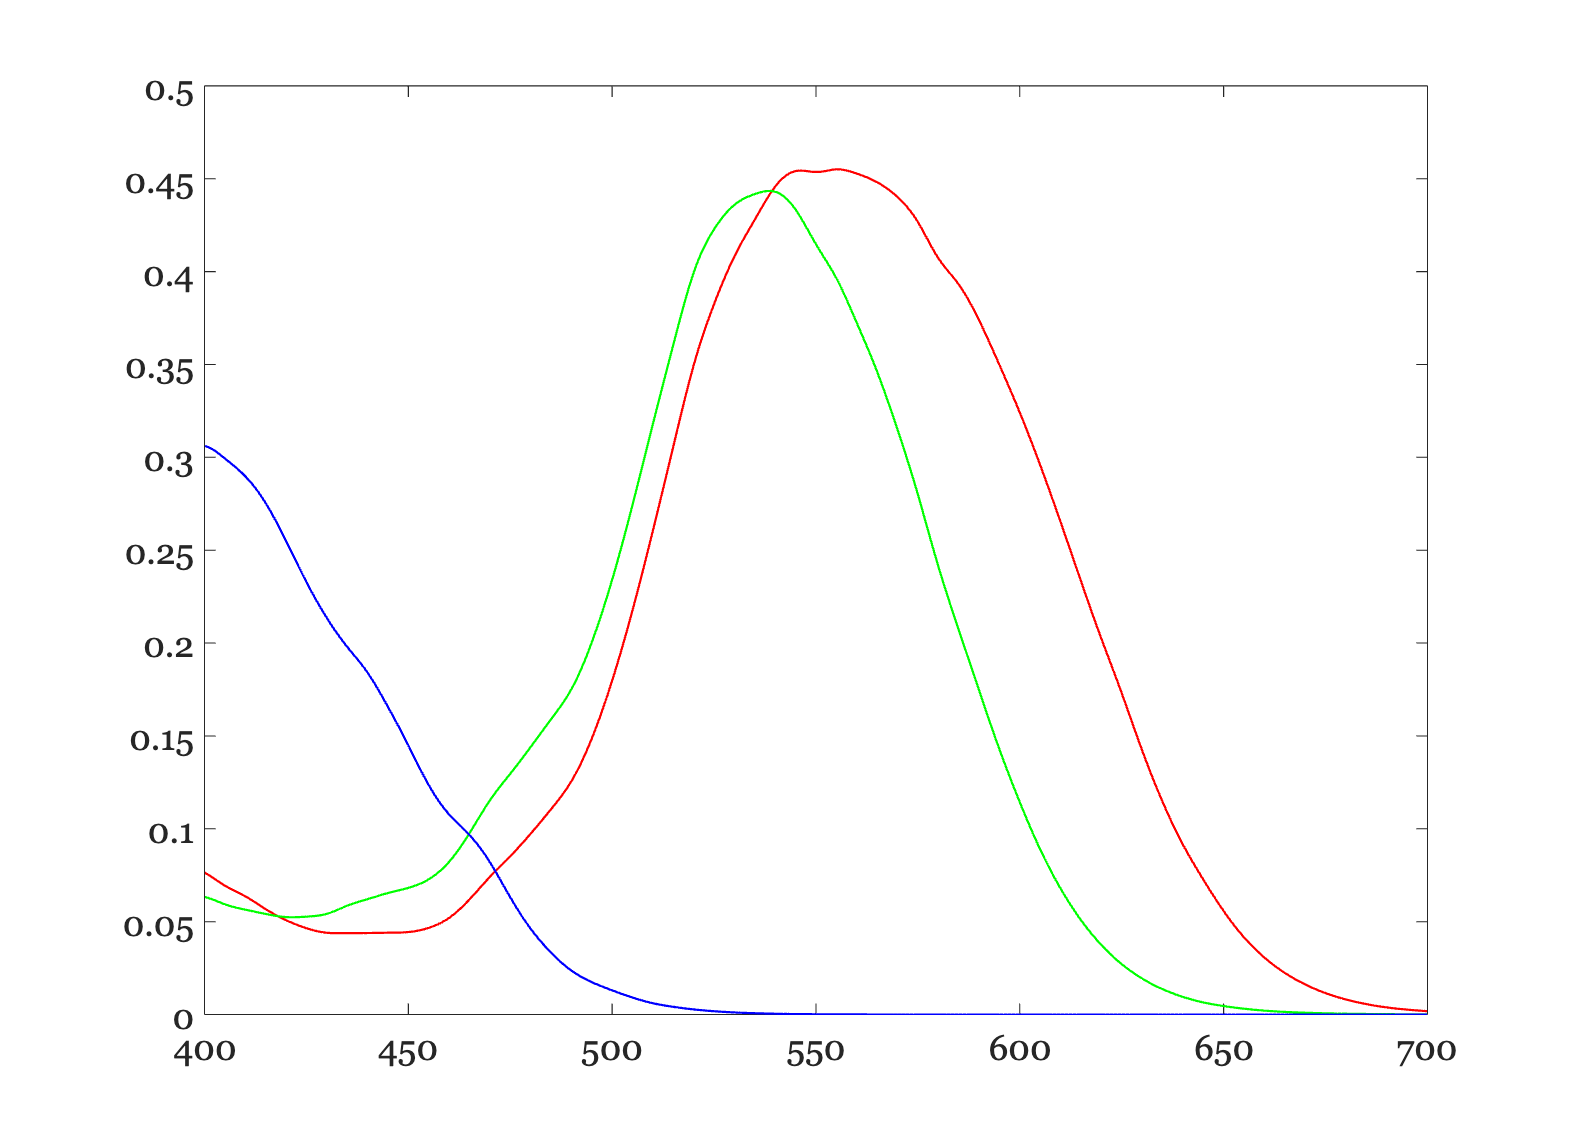

ieNewGraphWin; plot(wave,theMosaic.qe);

## Macular pigment and photopigment

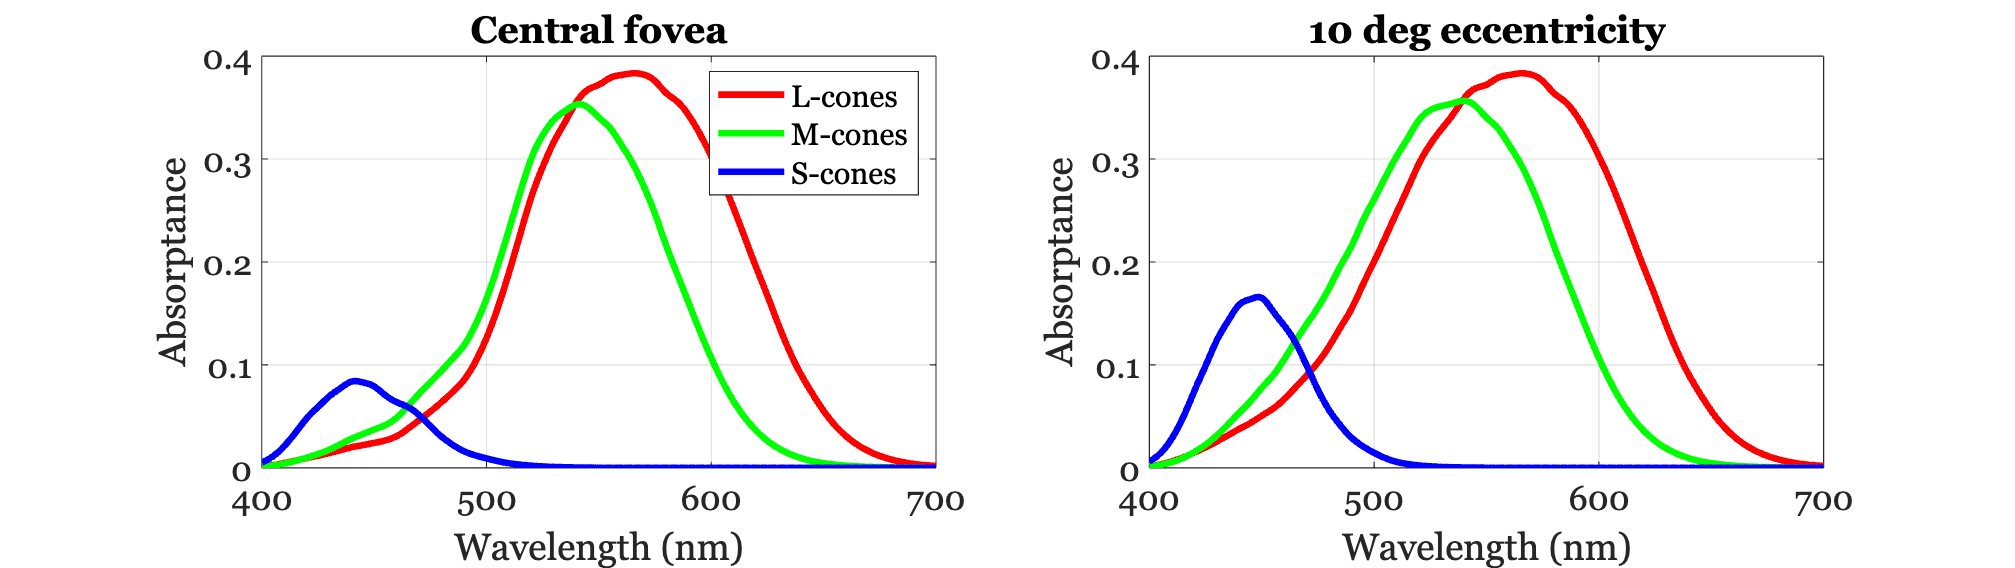

ieNewGraphWin([],'wide');
subplot(1,2,1)
theMosaic.macular.density = theMosaic.macular.eccDensity(0);
coneFundamentals = bsxfun(@times, theLens.transmittance', theMosaic.qe);
plot(wave,coneFundamentals,'Linewidth',3);
xlabel('Wavelength (nm)');
ylabel('Absorptance')
grid on;
legend('L-cones','M-cones','S-cones');
title('Central fovea');

subplot(1,2,2)
theMosaic.macular.density = theMosaic.macular.eccDensity(10); % 0.35 is Default
coneFundamentals = bsxfun(@times, theLens.transmittance', theMosaic.qe);
plot(wave,coneFundamentals,'Linewidth',3);
xlabel('Wavelength (nm)');
ylabel('Absorptance')
grid on;
title('10 deg eccentricity');

## PSFs 

I started out using the methods in ISETBioCSFGenerator.  Then, to simplify the code, I added a new function, oiPosition.  I used that in the Spitschan chapter.  To simplify here, I just stored out the oiData.

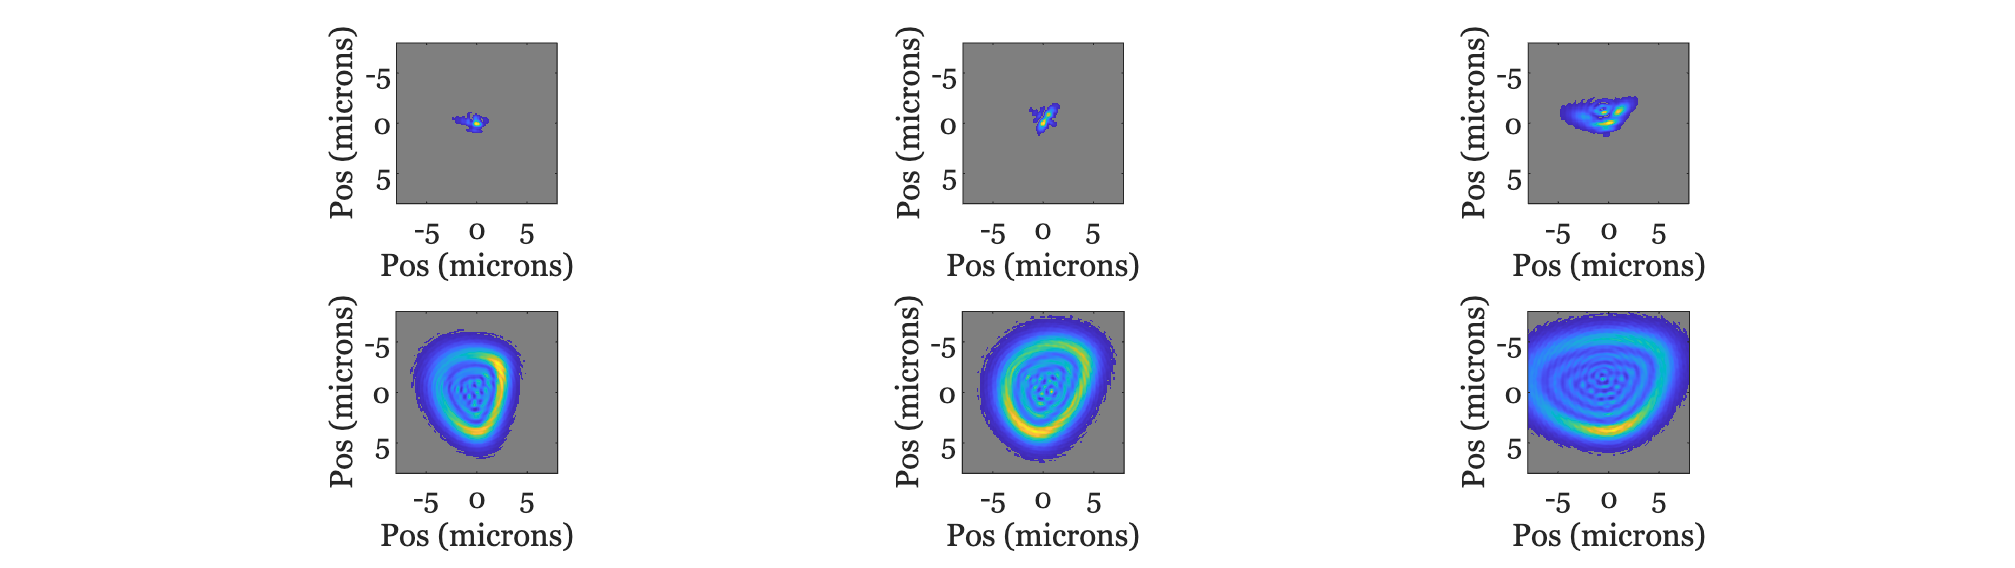

% I stopped the ISETBioCSFGenerator inside the
%
%     cMosaic.oiEnsembleGenerate
%
% method.  While there, I saved the key optics variables in the 'projects'
% directory.
%
% save('oiData','obj','oiSamplingGridDegs','varargin');

% Load the variables
load('oiData','obj','oiSamplingGridDegs','varargin');

% See oiPosition, not this!
%
% The key variable is obj, the ISETBio cMosaic
%
% obj.oiEnsembleGenerate runs to create the psfs given the parameters
%
% edit cMosaic.oiEnsembleGenerate
%
%  brings you to the code
%
% The meaning of the parameters is:
%    centerPos = oiSamplingGridDegs;
%{
varargin =
    {'zernikeDataBase'}    {'Polans2015'}
    {'subjectID'}            {[10]}
    {'pupilDiameterMM'}      {[3]}
    {'subtractCentral…'}     {[0]}
    {'zeroCenterPSF'}        {[1]}
    {'flipPSFUpsideDown'}    {[1]}
    {'wavefrontSpatia…'}    {[301]}
% Convert the varargin to a struct that we can edit
args = struct;
for ii=1:2:numel(varargin)
    args.(varargin{ii}) = varargin{ii+1};
end
%}

mp = parula(256);
mp(1:4,:) = repmat([0.5 0.5 0.5],[4,1]);
centers = [2,0; 8,0; 20,0];
theW = [7 3];
kk = 1;
ieNewGraphWin([],'wide');

for jj=1:numel(theW)
    for ii=1:size(centers,1)
        
        centerPos = centers(ii,:);
        
        args.zernikeDataBase = 'Artal2012'; % args.zernikeDataBase = 'Polans2015';
        args.subjectID       = 26;
        args.pupilDiameterMM = 4;
        args.subtractCentralRefraction = false;
        args.zeroCenterPSF = true;
        args.flipPSFUpsideDown = true;
        args.wavefrontSpatialSamples = 301;
        
        [oiEnsemble, psfEnsemble] = obj.oiEnsembleGenerate(centerPos,args);
        thisPSF = psfEnsemble{1};
        
        thisW = theW(jj);   % Select a wavelength, % 3 is 450 nm, 7 is 550 nm
        % h = mesh(thisPSF.supportX,thisPSF.supportY,thisPSF.data(:,:,thisW)/max2(thisPSF.data(:,:,thisW)));
        subplot(2,3,kk);
        imagesc(thisPSF.supportX,thisPSF.supportY,thisPSF.data(:,:,thisW)/max2(thisPSF.data(:,:,thisW)));
        axis image; colormap(mp);
        tMarks  = (-15:5:15); mn = -8; mx = 8;
        set(gca,'xtick',tMarks,'xlim',[mn mx],'ylim',[mn mx]);
        set(gca,'ytick',tMarks);
        xlabel('Pos (microns)');
        ylabel('Pos (microns)');
        zlabel('Relative intensity');
        kk = kk + 1;
        % title(sprintf('Wave %d Sub %d',thisPSF.supportWavelength(thisW),args.subjectID));
    end
end

## Compare Gaussian noise and stimulus dependent noise

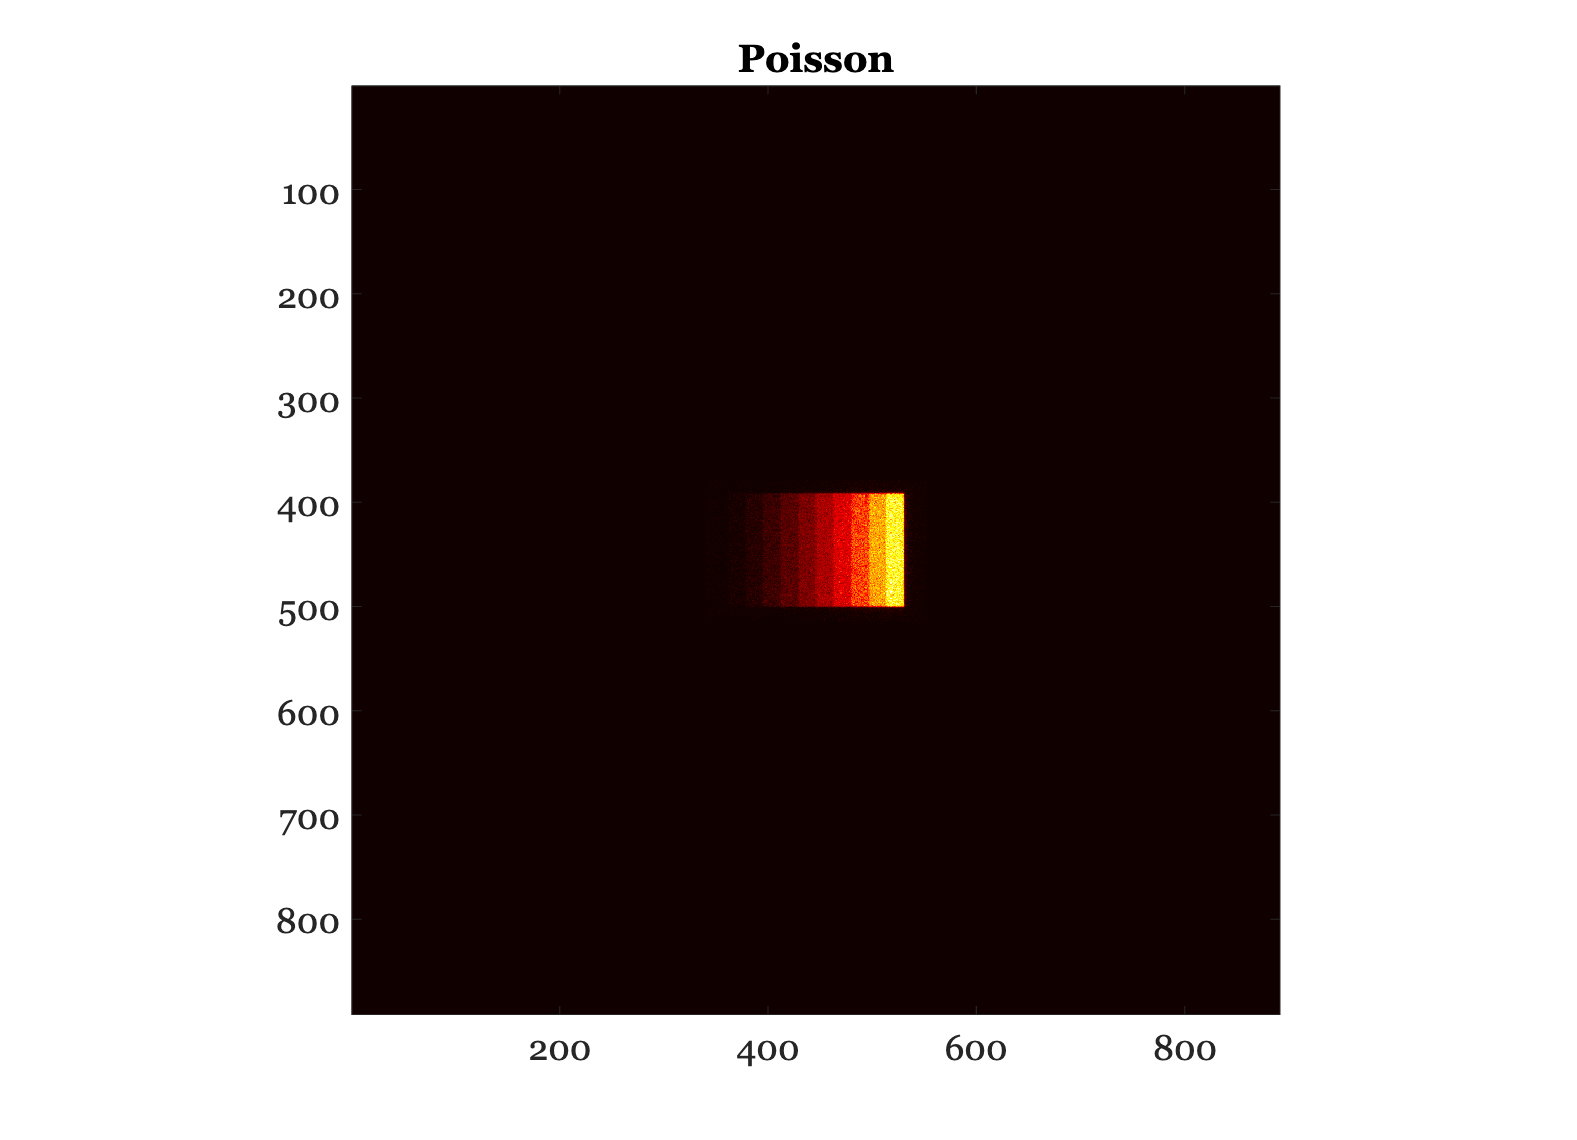

scene = sceneCreate('lstar');

scene = sceneSet(scene,'fov',5);

oi = oiCreate;
oi = oiCompute(oi,scene);

eTime = 0.002;
cDensity = [0 0 1 0];
fov = 6;

cmP = coneMosaicRect;
cmP.setSizeToFOV(fov);

% All M cones
cmP.spatialDensity = cDensity;
cmP.integrationTime = eTime;   % 10 ms
cmP.compute(oi);

photonNoise = cmP.absorptions;
mx = max(photonNoise(:));
ieNewGraphWin; imagesc(photonNoise,[0 mx]);
axis image; colormap(hot(128));
title('Poisson');brighten(0.3);

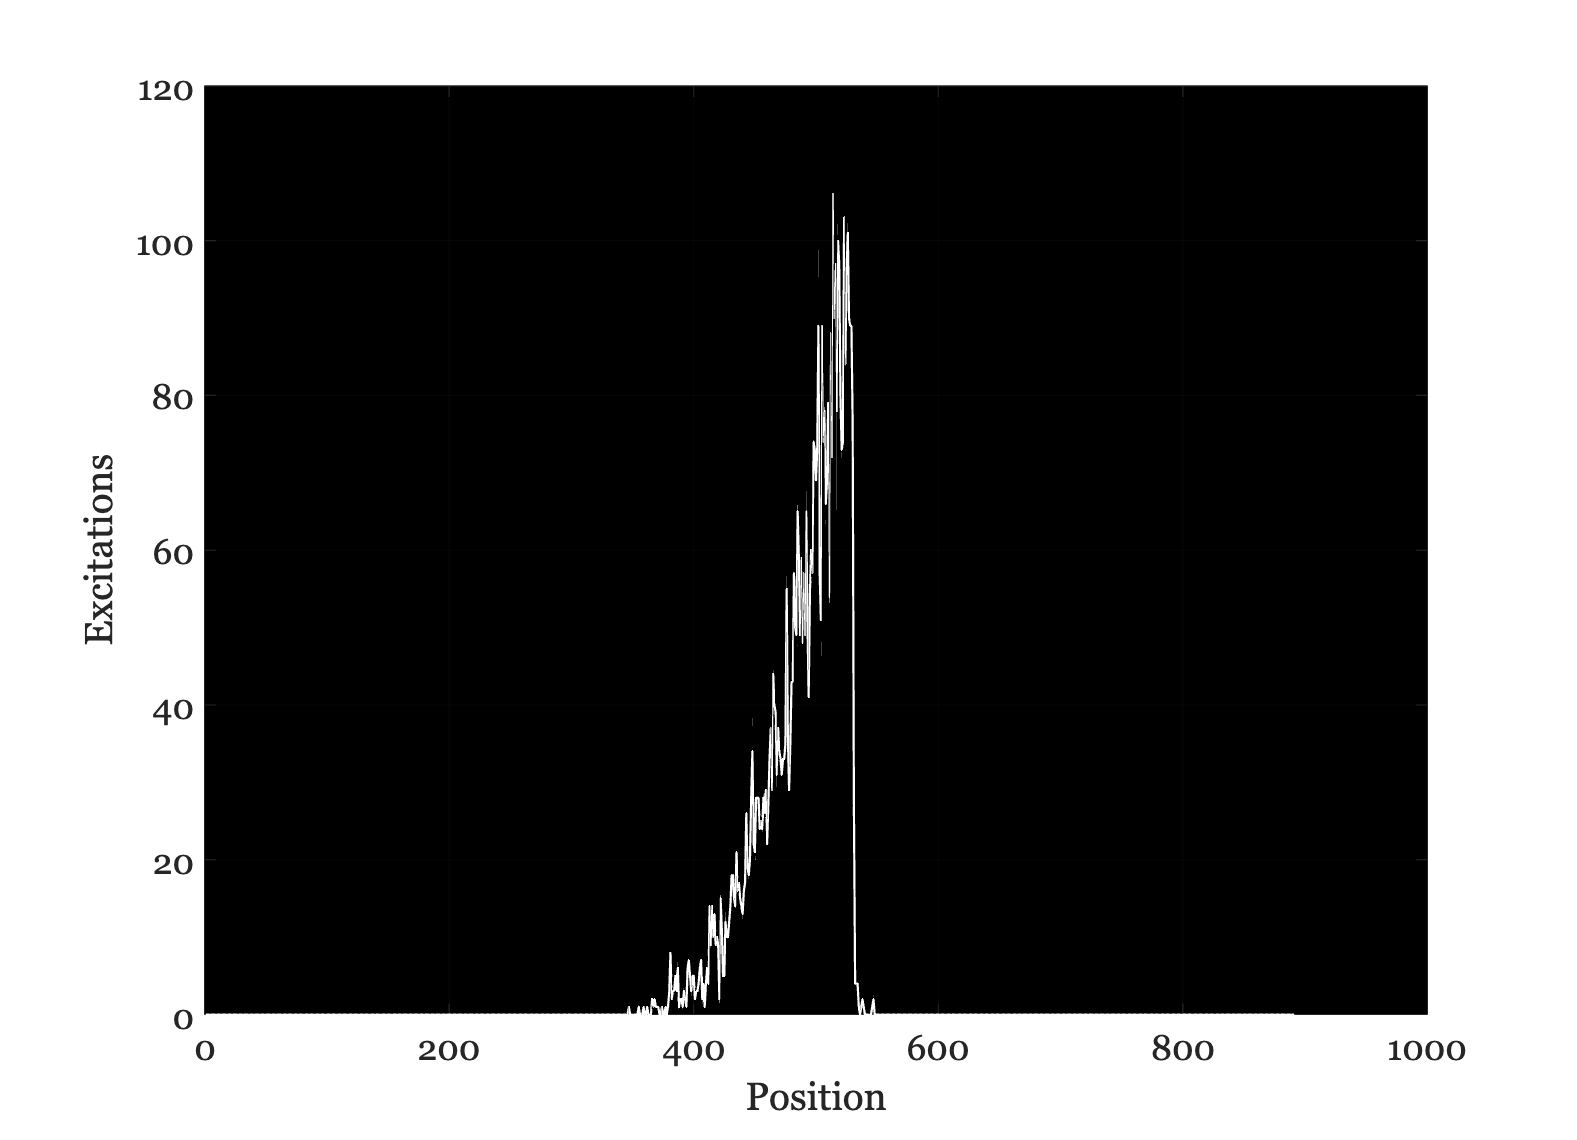


ieNewGraphWin; 
thisRow = photonNoise(400,:);
p = plot(thisRow,'LineWidth',1,'Color',[1 1 1]);
set(gca,'Color','k');

ylabel('Excitations'); xlabel('Position'); grid on;


cmP.name = 'photon';
% cmP.window;

### We compare with Gaussian here.

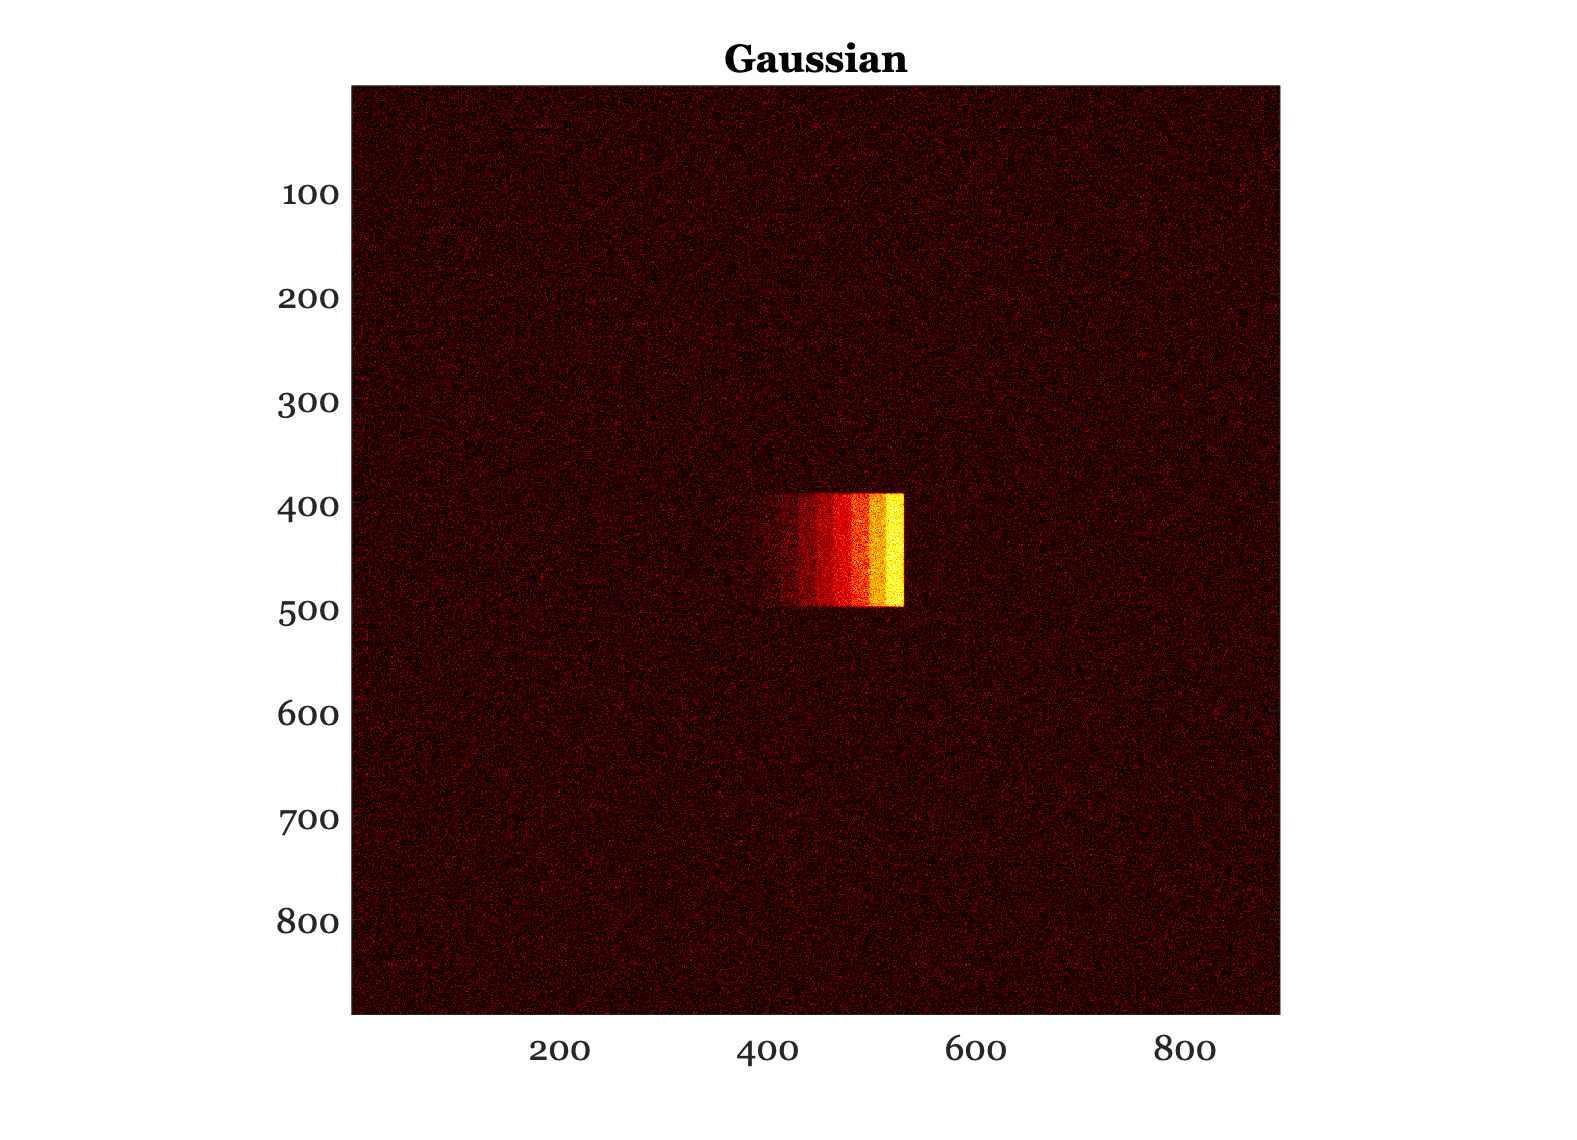

cmG = coneMosaicRect;
cmG.setSizeToFOV(fov);
cmG.spatialDensity = cDensity;
cmG.integrationTime = eTime;
cmG.noiseFlag = 'none';
cmG.compute(oi);

noNoise = cmG.absorptions;

mn = max(noNoise(:));
equivNoise = randn(size(noNoise))*sqrt(mn);

gaussNoise = noNoise + equivNoise;
gaussNoise(gaussNoise<0) = 0;
mx = max(gaussNoise(:));

ieNewGraphWin; imagesc(gaussNoise,[0 mx]);
axis image; colormap(hot(128));
title('Gaussian'); brighten(0.3);

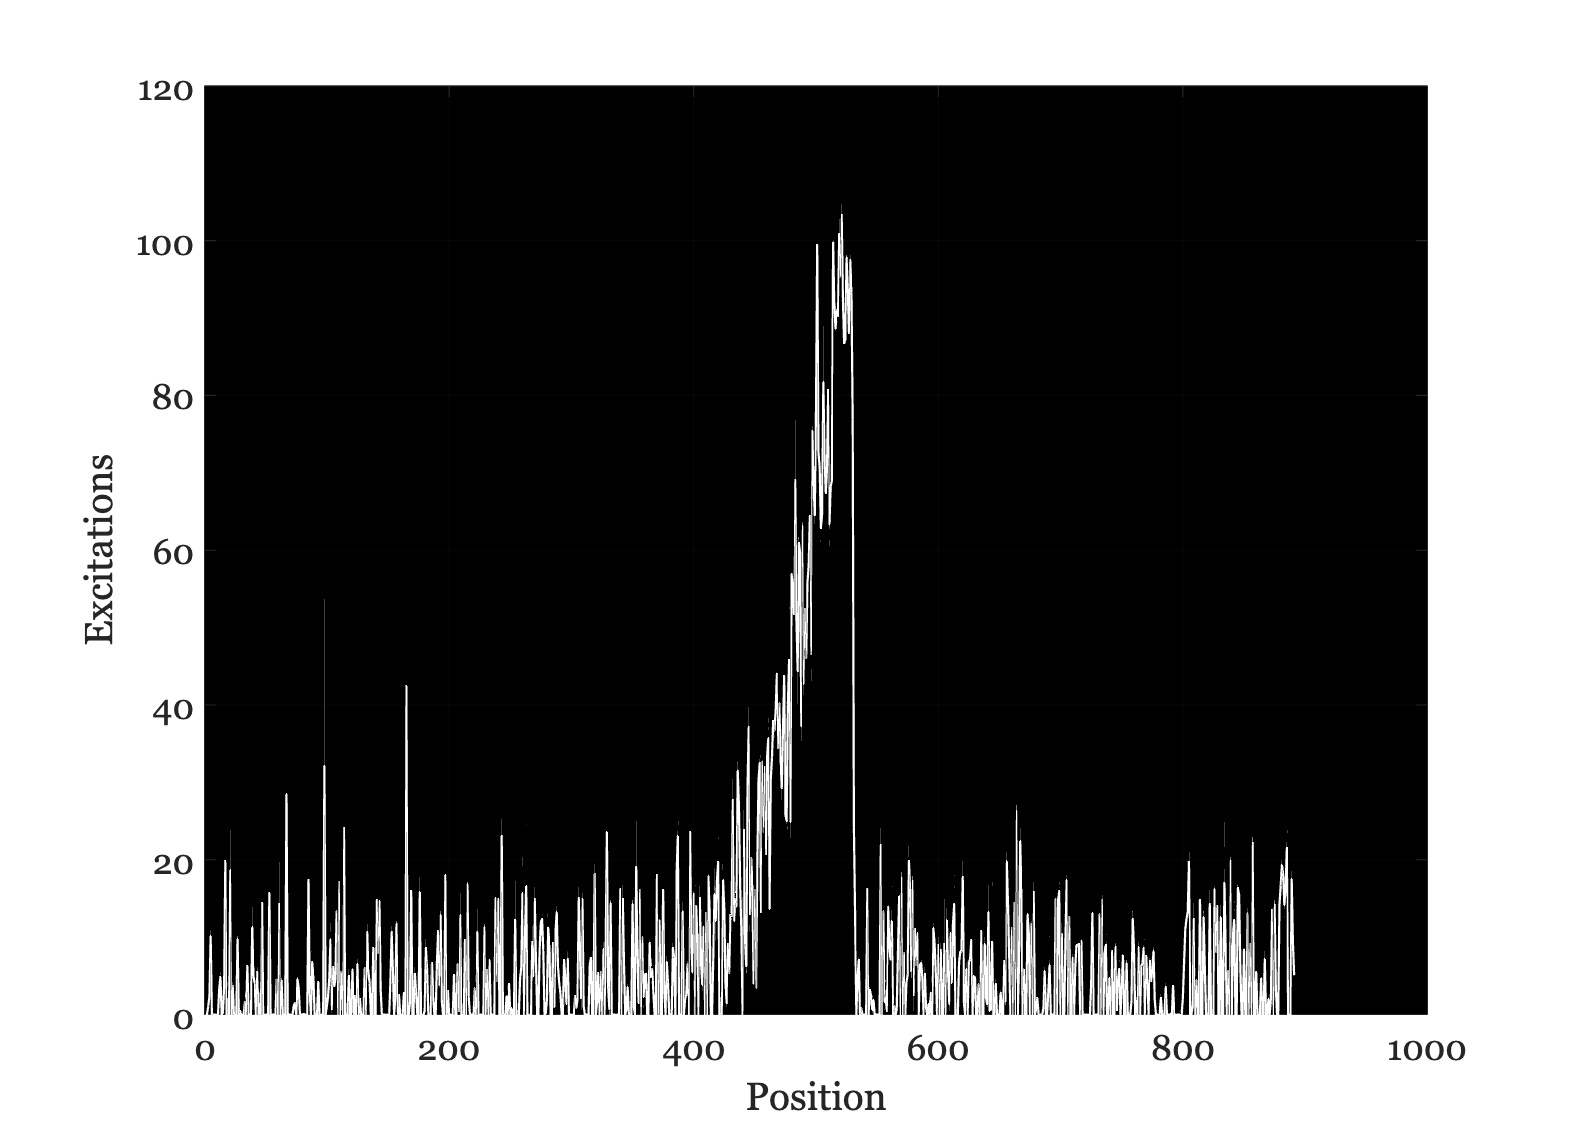

ieNewGraphWin; 
thisRow = gaussNoise(400,:);
p = plot(thisRow,'LineWidth',1,'Color',[1 1 1]);
ylabel('Excitations'); xlabel('Position'); grid on;
set(gca,'Color','k');